# Simple chatbot example using MATLAB

It seems everyone is talking about ChatGPT these days thanks to its impressive capabilities to mimic human speech. It is obviously a very sophisticated AI, but it is based on the language model that predicts the next words based on the preceding words.

N-gram language models are very simple and you can code it very easily in MATLAB with Text Analytics Toolbox. Here is an example of a bot that generates random Shakespeare-like sentences. (this is based on my [old blog post](https://blogs.mathworks.com/loren/2015/09/09/text-mining-shakespeare-with-matlab/)).

## **Import data**

Let's start by importing Romeo and Juliet from Gutenberg Project.

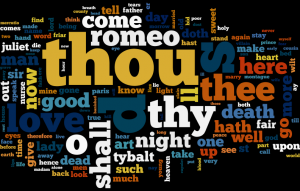

rawtxt = webread('http://www.gutenberg.org/files/1513/1513-h/1513-h.htm');
tree = htmlTree(rawtxt);

## **Preprocess text**

We only want to include actual lines characters speak, not stage directions, etc.

subtree = findElement(tree,'p:not(.scenedesc):not(.right):not(.letter)');
romeo = extractHTMLText(subtree);

We also don't want empty rows and the prologue.

romeo(romeo == '') = [];
romeo(1:5) = [];
romeo(1:5)

ans = 5×1 string array
    "SAMPSON.↵Gregory, on my word, we’ll not carry coals."
    "GREGORY.↵No, for then we should be colliers."
    "SAMPSON.↵I mean, if we be in choler, we’ll draw."
    "GREGORY.↵Ay, while you live, draw your neck out o’ the collar."
    "SAMPSON.↵I strike quickly, being moved."


Each line start with the name of the character, followed by `.` and return character. We can use this pattern to split the names from the actual lines.

pat = "\." + newline;
cstr = regexp(romeo,pat,'split','once');

This creates a cell array because not all rows can be split using the pattern, because some lines run multiple rows. Let's create a new string array and extract content of the cell array into it.

dialog = strings(size(cstr,1),2);
is2 = cellfun(@length,cstr) == 2;
dialog(is2,:) = vertcat(cstr{is2});
dialog(~is2,2) = vertcat(cstr{~is2});
dialog = replace(dialog,newline, " ");
dialog = eraseBetween(dialog,'[',']','Boundaries','inclusive');
dialog(1:5,:)

ans = 5×2 string array
    "SAMPSON"    "Gregory, on my word, we’ll not carry coals."          
    "GREGORY"    "No, for then we should be colliers."                  
    "SAMPSON"    "I mean, if we be in choler, we’ll draw."              
    "GREGORY"    "Ay, while you live, draw your neck out o’ the collar."
    "SAMPSON"    "I strike quickly, being moved."                       


## **N-grams**

An n-gram is a sequence of words that appear together in a sentence. Commonly word tokens are used, and they are unigrams. You can also use a pair of words, and that's a bigram. Trigrams use three words, etc.

Therefore, the next step is to tokenize the lines, which are in the second column of dialog.

doc = tokenizedDocument(dialog(:,2));
doc = lower(doc);
doc(doclength(doc) < 3) = [];

We also need to add sentence markers <s> and </s> to indicate the start and the end of sentences.

doc = docfun(@(x) ['<s>' x '</s>'], doc);
doc(1:5)

ans =   5×1 tokenizedDocument:

    13 tokens: <s> gregory , on my word , we’ll not carry coals . </s>
    11 tokens: <s> no , for then we should be colliers . </s>
    14 tokens: <s> i mean , if we be in choler , we’ll draw . </s>
    17 tokens: <s> ay , while you live , draw your neck out o ’ the collar . </s>
     9 tokens: <s> i strike quickly , being moved . </s>


## **Language models**

Language models are used to predict a sequence of words in a sentence based on chained conditional probabilities. These probabilities are estimated by mining a collection of text known as a corpus and 'Romeo and Juliet' is our corpus. Language models are made up of such word sequence probabilities.

Let's start by generating a bag of N-grams, which contains both the list of words and their frequencies.

bag1 = bagOfWords(doc);
bag2 = bagOfNgrams(doc);
bag3 = bagOfNgrams(doc,'NgramLengths',3);

We can then use the frequencies to calculate the probabilities.

Here is a bigram example of how you would compute conditional probability of "art" following "thou".


$$P\left(\mathrm{art}\left|\mathrm{thou}\right.\right)=\frac{\mathrm{count}\left(\mathrm{thou}\;\mathrm{art}\right)}{\mathrm{count}\left(\mathrm{thou}\right)}$$


Here is an example for trigrams that computes conditional probability of "romeo" following "thou art".


$$\left.P\left(\mathrm{romeo}\right|\mathrm{thou}\;\mathrm{art}\right)=\frac{\mathrm{count}\left(\mathrm{thou}\;\mathrm{art}\;\mathrm{romeo}\right)}{\mathrm{count}\left(\mathrm{thou}\;\mathrm{art}\right)}$$


Let's create a bigram language model Mdl2, which is a matrix whose rows corresponds to the first words in the bigram and the columns the second, using dictionary data type introduced in R2022b. 

Vocab1 = bag1.Vocabulary;
Vocab2 = bag2.Ngrams;
Mdl2 = dictionary;
for ii = 1:size(Vocab2,1)
    tokens = Vocab2(ii,:);
    isPrev = Vocab1 == tokens(1);
    Mdl2(join(tokens)) = sum(bag2.Counts(:,ii))/sum(bag1.Counts(:,isPrev)); 
end

Here are the top 5 words that follow 'thou' sorted by probability.

T = entries(Mdl2);
myKeys = split(T.Key);
thou_entries = T(myKeys(:,1) == 'thou',:);
thou_entries = sortrows(thou_entries,"Value","descend");
thou_entries(1:5,:)

ans = 5×2 table
        Key          Value  
    ____________    ________

    "thou art"       0.10145
    "thou wilt"     0.076087
    "thou hast"     0.072464
    "thou shalt"    0.032609
    "thou not"      0.032609


Let's also create a trigram language model Mdl3

Vocab3 = bag3.Ngrams;
Mdl3 = dictionary;
for ii = 1:size(Vocab3,1)
    tokens = Vocab3(ii,:);
    isPrev = all(Vocab2 == tokens(1:2),2);
    Mdl3(join(tokens)) = sum(bag3.Counts(:,ii))/sum(bag2.Counts(:,isPrev));
end

And the top 5 words that follow 'thou shalt' sorted by probability.

T = entries(Mdl3);
myKeys = split(T.Key);
thou_shalt_entries = T(join(myKeys(:,1:2)) == "thou shalt",:);
thou_shalt_entries = sortrows(thou_shalt_entries,"Value","descend");
thou_shalt_entries(1:5,:)

ans = 5×2 table
             Key              Value 
    _____________________    _______

    "thou shalt be"          0.22222
    "thou shalt not"         0.11111
    "thou shalt know"        0.11111
    "thou shalt live"        0.11111
    "thou shalt continue"    0.11111


## **Predict next word**

We can then use `nextWord` function to generate text, which is defined below.

outtext = "<s>";
outtext = [outtext nextWord(Mdl2,outtext)];
while outtext(end) ~= "</s>"
    outtext = [outtext nextWord(Mdl3,outtext(end-1:end))];
    if outtext(end) == "."
        break
    end
end
strtrim(replace(join(outtext),{'<s>','</s>'},''))

ans = "benedicite ! what early tongue so sweet saluteth me ?"

## **Generate text**

We can turn this into a function `textGen` as well, which is also defined below.

outtext = textGen(Mdl2,Mdl3,firstWord='romeo')

outtext = 6×1 string array
    "romeo slaughter’d and is he gone , ’ quoth my husband ."
    "romeo , good benvolio ; beat down their fatal points , and vice sometime’s by action dignified ."
    "romeo ! romeo , arise , thou hadst been poor john ."
    "romeo , that presses them , in that hit you miss : she’ll not be found , being moved ."
    "romeo , and can never find what names the writing person hath here writ , give leave awhile ; fie , fie , fie ! what early tongue so sweet saluteth me ?"
    "romeo , romeo must not live ."
